clc; clear all; close all;


## Import Data

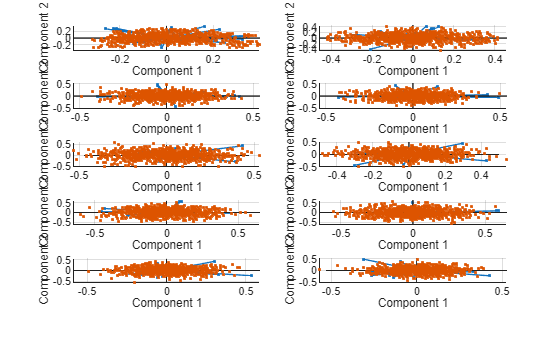

model(1).X0 = readmatrix("d00_te.dat");
model(1).varNames = ["x1-AFeed", "x2-DFeed", "x3-EFeed", "x4-TotalFeed", "x5-RecycleFlow", ...
    "x6-ReactorFeedRate", "x7-ReactorPressure", "x8-ReactorLevel", "x9-ReactorTemperature", ...
    "x10-PurgeRate", "x11-SeparatorTemperature", "x12-SeparatorLevel", ...
    "x13-SeparatorPressure", "x14-SeparatorUnderflow", "x15-StripperLevel", "x16-StripperPressure", ...
    "x17-StripperUnderflow", "x18-StripperTempreature",...
    "x19-StripperSteamFlow", "x20-CompressorWork", "x21-ReactorCoolOutT", "x22-SeparCoolOutT", ...
    "x23-ReactorCompA", "x24-ReactorCompB", "x25-ReactorCompC", "x26-ReactorCompD", "x27-ReactorCompE", ...
    "x28-ReactorCompF", "x29-PurgeCompA", "x30-PurgeCompB", "x31-PurgeCompC", "x32-PurgeCompD", ...
    "x33-PurgeCompE", "x34-PurgeCompF", "x35-PurgeCompG", "x36-PurgeCompH", ...
    "x37-ProdCompD", "x38-ProdCompE", "x39-ProdCompF", "x40-ProdCompG", "x41-ProdCompH", "x42-DFeedFlow", ...
    "x43-EFeedFlow", "x44-AFeedFlow", "x45-TotalFeedFlow", "x46-CompressorRecycleWave", "x47-PurgeValve", ...
    "x48-SeparatorProdLFlow", "x49-StripperProdLFlow", "x50-StripperSteamValve", "x51-ReactorCoolingWaterFlow", ...
    "x52-CondenserCoolingWaterFlow"];

% Center and scale
[model(1).X, model(1).mu, model(1).sigma] = zscore(model(1).X0);

% Create PCA model
[model(1).P, model(1).T, model(1).latent, model(1).tsq, model(1).expl] = ...
    pca(model(1).X, 'Centered', false, 'NumComponents', 20);
% Careful! MATLAB's T2 doesn't take into account the number of components
% you apply.

% Taking a look at the biplots and control charts for the healthy model
figure;
for i = 1:10
    subplot(5,2,i);
    biplot(model(1).P(:,i:i+1), 'Scores', model(1).T(:,i:i+1));

end

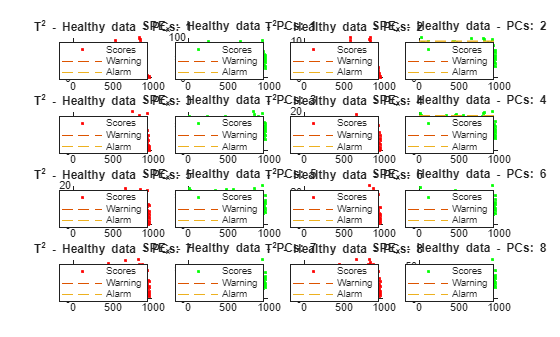

% Control Charts
[model(1).row, model(1).col]    =  size(model(1).X);
figure;
ii = 1;
for i = 1:8
    model(1).ncomp(i).T2        = t2comp(model(1).X, model(1).P, model(1).latent, i);
    model(1).ncomp(i).T2warning   = mean(model(1).ncomp(i).T2) + 2 * std(model(1).ncomp(i).T2);
    model(1).ncomp(i).T2alarm = mean(model(1).ncomp(i).T2) + 3 * std(model(1).ncomp(i).T2);

    subplot(4,4,ii); ii = ii + 1;
    scatter(1:model(1).row, model(1).ncomp(i).T2, 'r.');
    hold on  
    plot([1, model(1).row], [model(1).ncomp(i).T2warning, model(1).ncomp(i).T2warning], '--');
    plot([1, model(1).row], [model(1).ncomp(i).T2alarm, model(1).ncomp(i).T2alarm], '--');
    title("T^2 - Healthy data - PCs: " + string(i));
    legend(["Scores", "Warning", "Alarm"]);

    model(1).ncomp(i).SPEx          = qcomp(model(1).X, model(1).P, i);
    model(1).ncomp(i).SPEwarning    = mean(model(1).ncomp(i).SPEx) + 2 * std(model(1).ncomp(i).SPEx);
    model(1).ncomp(i).SPEalarm      = mean(model(1).ncomp(i).SPEx) + 3 * std(model(1).ncomp(i).SPEx);
    
    subplot(4,4,ii); ii = ii + 1;
    scatter(1:model(1).row, model(1).ncomp(i).SPEx, 'g.');
    hold on
    plot([1, model(1).row], [model(1).ncomp(i).SPEwarning, model(1).ncomp(i).SPEwarning], '--');
    plot([1, model(1).row], [model(1).ncomp(i).SPEalarm,   model(1).ncomp(i).SPEalarm], '--');
    title("SPE_x - Healthy data - PCs: " + string(i));
    legend(["Scores", "Warning", "Alarm"]);

end

## Faulty Data Import

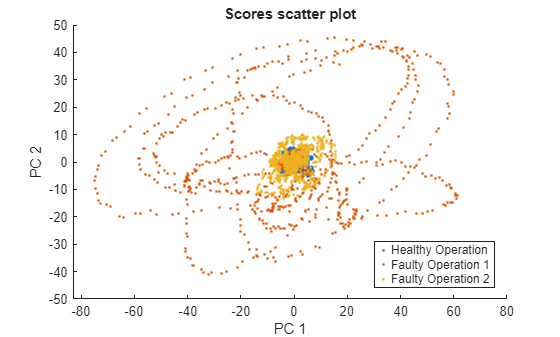

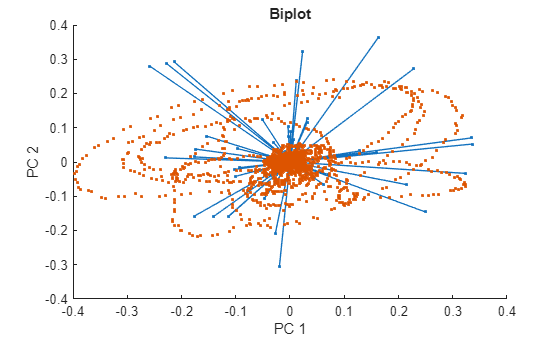

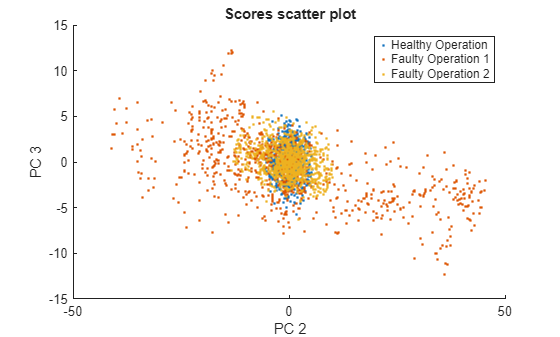

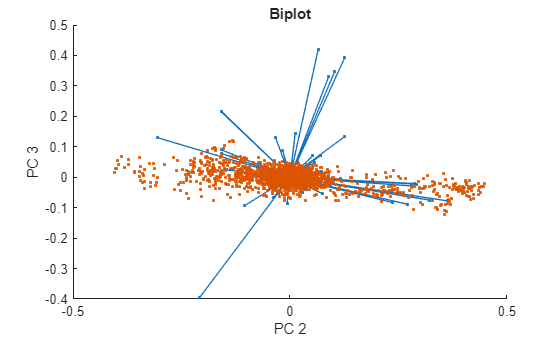

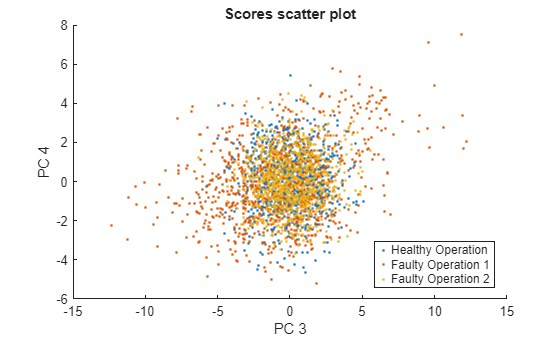

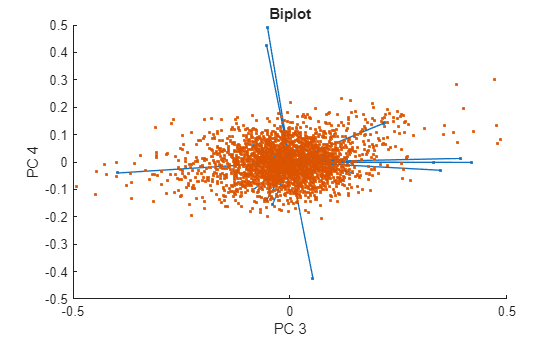

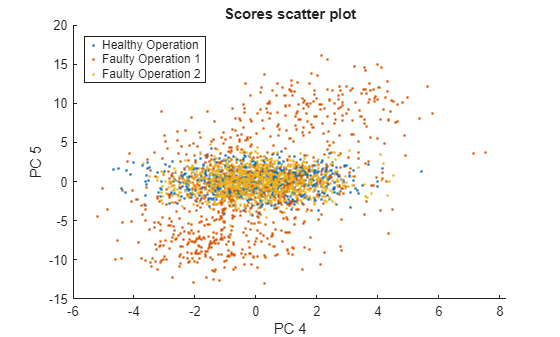

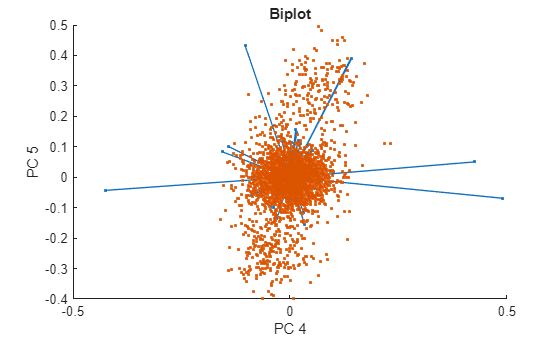


% Reading and projecting the new samples
model(2).X0 = readmatrix("d13_te.dat");
model(3).X0 = readmatrix("d10_te.dat");

% Centering and scaling data
model(2).X  = normalize(model(2).X0, 'center', model(1).mu, 'scale', model(1).sigma);
model(3).X  = normalize(model(3).X0, 'center', model(1).mu, 'scale', model(1).sigma);

for i = 1:3
    for j = 1:20
        model(i).ncomp(j).R2 = calculateR2(model(i).X, model(1).P, j);
    end
end

figure; 
plot(1:20, [model(1).ncomp.R2]);
hold on
plot(1:20, [model(2).ncomp.R2]);
plot(1:20, [model(3).ncomp.R2]);
legend(["Model Healthy", "Model Faulty 1", "Model Faulty 2"]);

% Projecting samples in model
model(2).T  = model(2).X * model(1).P;
model(3).T  = model(3).X * model(1).P;

% Analyzing biplot
[model(1).row, model(1).col] = size(model(1).X);
[model(2).row, model(2).col] = size(model(2).X);
[model(3).row, model(3).col] = size(model(3).X);

class1      = ones(model(1).row, 1);
class2      = ones(model(2).row, 1)*2;
class3      = ones(model(3).row, 1)*3;

class       = categorical([class1; class2; class3]);

% Extended faulty + healthy
model(4).T = [model(1).T; model(2).T; model(3).T];

%figure; ii = 1;
for i = 1:8
    figure
    hold on
    %subplot(4,4,ii); ii = ii + 1;
    gscatter(model(4).T(:,i), model(4).T(:,i+1), class);
    title("Scores scatter plot")
    xlabel("PC " + string(i));
    ylabel("PC " + string(i+1));
    legend(["Healthy Operation", "Faulty Operation 1", "Faulty Operation 2"]);
    hold off
    figure
    hold on
    %subplot(4,4,ii); ii = ii + 1;
    biplot(model(1).P(:,i:i+1), 'Scores', model(4).T(:,i:i+1));
    title("Biplot")
    xlabel("PC " + string(i));
    ylabel("PC " + string(i+1));
    hold off

end

## In-depth plot

chosenPC = 6;

for i = 1:model(1).col
    model(1).varNameNumber(i) = "x" + string(i);
end

figure; ii = 1;
for i = chosenPC
    subplot(1,2,ii); ii = ii + 1;
    gscatter(model(4).T(:,i), model(4).T(:,i+1), class);
    title("Scores scatter plot")
    xlabel("PC " + string(i));
    ylabel("PC " + string(i+1));
    legend(["Healthy Operation", "Faulty Operation"]);

    subplot(1,2,ii); ii = ii + 1;
    biplot(model(1).P(:,i:i+1), 'Scores', model(4).T(:,i:i+1), 'VarLabels', model(1).varNameNumber);
    title("Biplot")
    xlabel("PC " + string(i));
    ylabel("PC " + string(i+1));

end
% Loadings Plot
figure;
bar(model(1).P(:,i));
xticks(1:model(1).col);
xticklabels(model(1).varNames);

## Single PC-based control

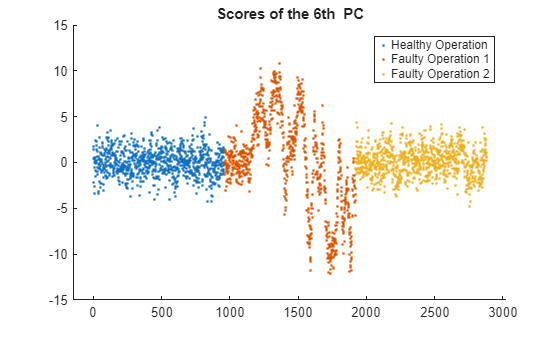

figure;
gscatter(1:(model(1).row + model(2).row + model(3).row), model(4).T(:,i), class);
title("Scores of the " + i + "th  PC");
legend(["Healthy Operation", "Faulty Operation 1", "Faulty Operation 2"]);

## Computing control charts

for i = 1:10

    % Compute T2
    model(1).ncomp(i).T2        = t2comp(model(1).X, model(1).P, model(1).latent, i);
    model(2).ncomp(i).T2        = t2comp(model(2).X, model(1).P, model(1).latent, i);
    model(3).ncomp(i).T2        = t2comp(model(3).X, model(1).P, model(1).latent, i);

    % Compute SPEx
    model(1).ncomp(i).SPEx      = qcomp(model(1).X, model(1).P, i);
    model(2).ncomp(i).SPEx      = qcomp(model(2).X, model(1).P, i);
    model(3).ncomp(i).SPEx      = qcomp(model(3).X, model(1).P, i);


    % Compute T2 limites
    model(1).ncomp(i).T2lim     = mean(model(1).ncomp(i).T2) + 3 * std(model(1).ncomp(i).T2);
    model(1).ncomp(i).T2limwar  = mean(model(1).ncomp(i).T2) + 2 * std(model(1).ncomp(i).T2);

    % Compute SPEx limits
    model(1).ncomp(i).SPExlim   = mean(model(1).ncomp(i).SPEx) + 3 * std(model(1).ncomp(i).SPEx);
    model(1).ncomp(i).SPExlimwar= mean(model(1).ncomp(i).SPEx) + 2 * std(model(1).ncomp(i).SPEx);

end


## Analyzing control charts

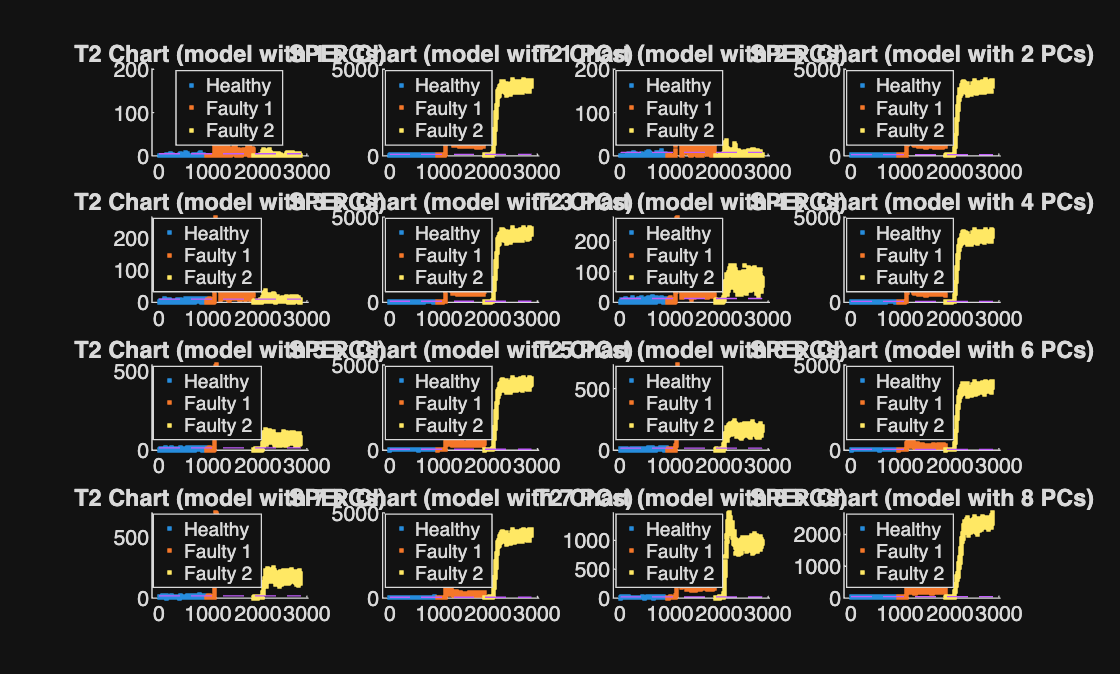

figure; ii = 1;
for i = 1:8
    
    model(4).ncomp(1).T2 = [model(1).ncomp(i).T2; model(2).ncomp(i).T2; model(3).ncomp(i).T2];
    model(4).row = model(1).row + model(2).row + model(3).row;
    subplot(4, 4, ii); ii = ii + 1;
    gscatter(1:model(4).row, [model(4).ncomp(1).T2], class);
    hold on
    plot([1, model(4).row], [model(1).ncomp(i).T2lim, model(1).ncomp(i).T2lim], '--');
    hold off
    title("T2 Chart (model with " + string(i) + " PCs)");
    legend(["Healthy", "Faulty 1", "Faulty 2"]);

    model(4).ncomp(i).SPEx = [model(1).ncomp(i).SPEx; model(2).ncomp(i).SPEx; model(3).ncomp(i).SPEx];
    subplot(4, 4, ii); ii = ii + 1;
    gscatter(1:model(4).row, model(4).ncomp(i).SPEx, class);
    hold on
    plot([1, model(4).row], [model(1).ncomp(i).SPExlim, model(1).ncomp(i).SPExlim], '--');
    hold off
    title("SPEx Chart (model with " + string(i) + " PCs)");
    legend(["Healthy", "Faulty 1", "Faulty 2"]);
end

## Alarms and Warnings - First sample above control limits

for i = 2:3
    model(i).idxT2       = find(model(i).ncomp(chosenPC).T2   > model(1).ncomp(chosenPC).T2lim);
    model(i).idxSPEx     = find(model(i).ncomp(chosenPC).SPEx > model(1).ncomp(chosenPC).SPExlim);
    model(i).idxT2war    = find(model(i).ncomp(chosenPC).T2   > model(1).ncomp(chosenPC).T2limwar);
    model(i).idxSPExwar  = find(model(i).ncomp(chosenPC).SPEx > model(1).ncomp(chosenPC).SPExlimwar);
end


## Control charts contribution

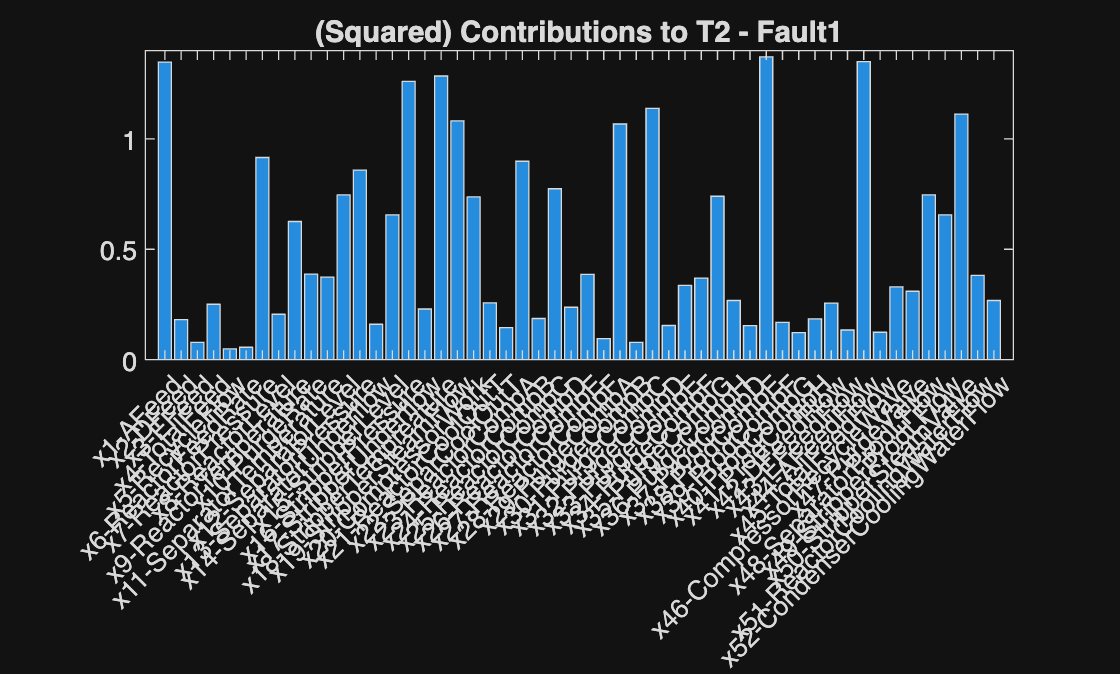

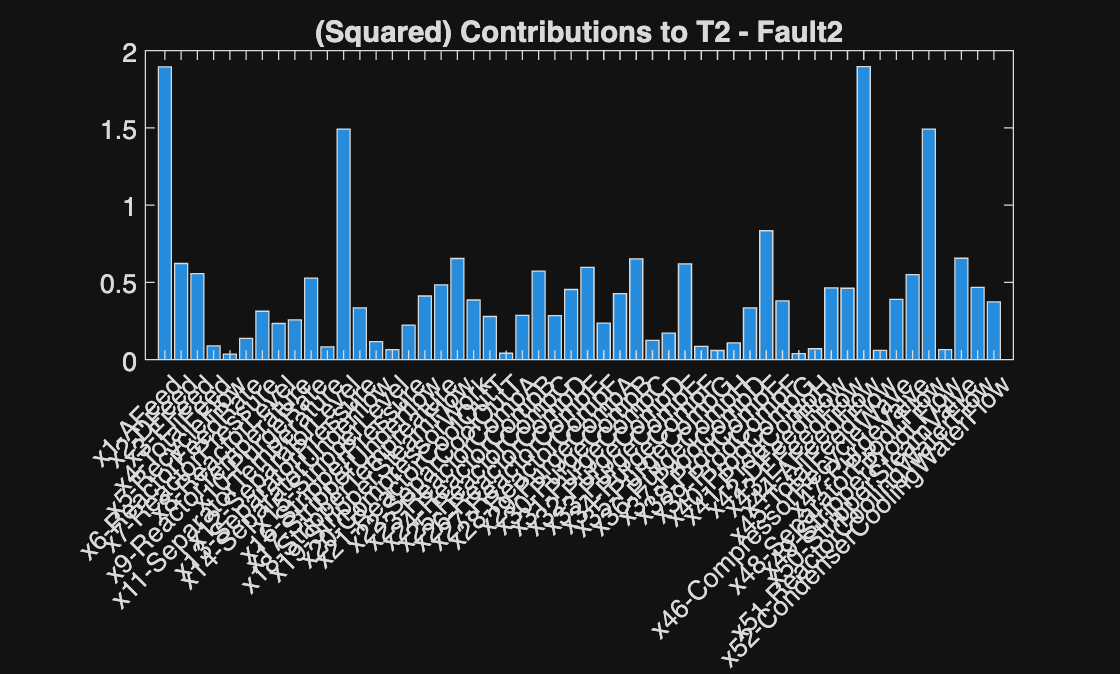

for i = 2:3
    model(i).obs(model(i).idxT2(1)).T2varc       = t2contr(model(i).X(model(i).idxT2(1),:), model(1).P, model(1).latent, 5);
    model(i).obs(model(i).idxSPEx(1)).SPExvarc   = qcontr(model(i).X(model(i).idxSPEx(1),:), model(1).P, 5);
end

for i = 2:3
figure;
bar(model(i).obs(model(i).idxT2(1)).T2varc);
xticklabels(model(1).varNames);
xticks(1:model(1).col);
title("(Squared) Contributions to T2 - Fault" + string(i-1));
xtickangle(45)
end

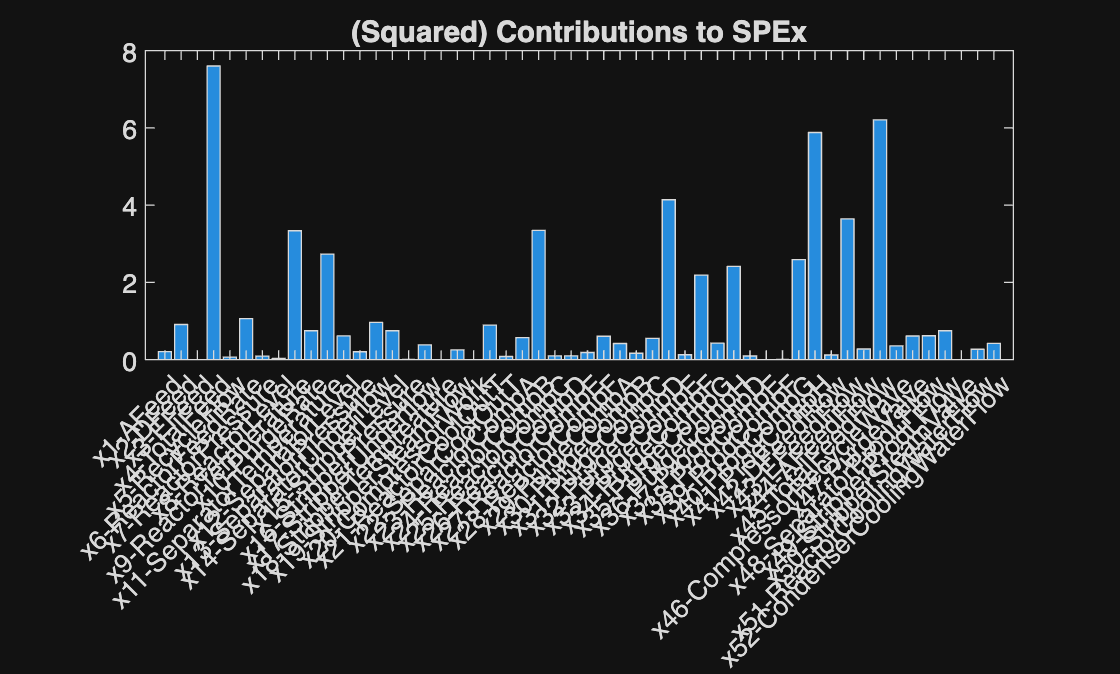

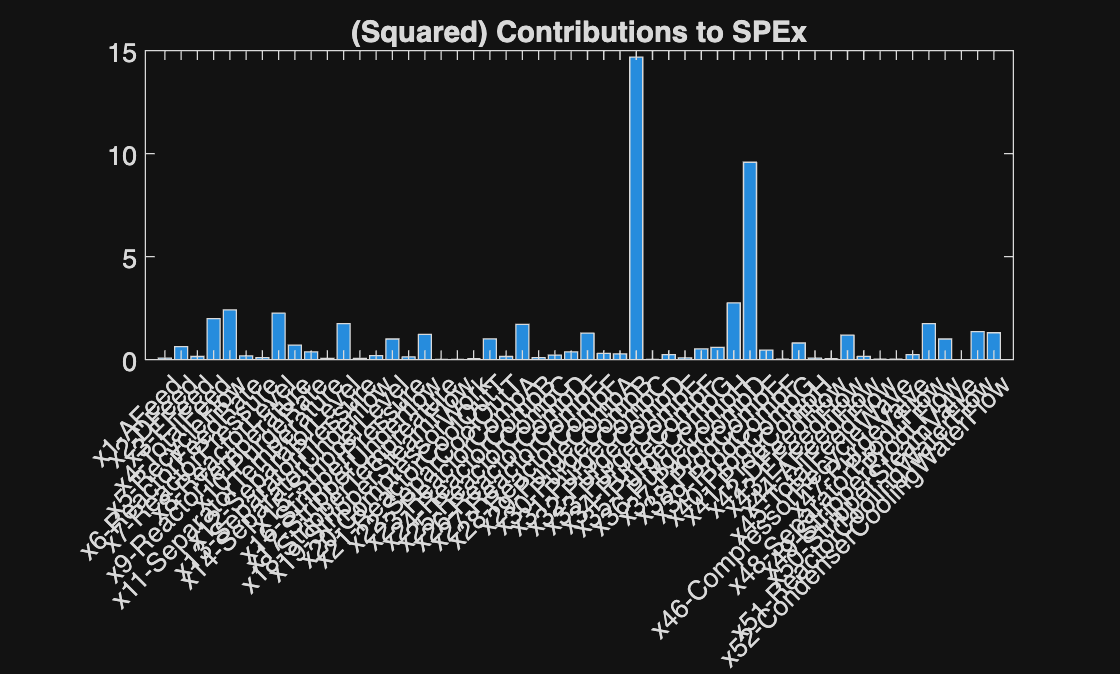


for i = 2:3
figure;
bar(model(i).obs(model(i).idxSPEx(1)).SPExvarc);
xticklabels(model(1).varNames);
xticks(1:model(1).col);
title("(Squared) Contributions to SPEx");
xtickangle(45)
end

## Specific Modelling Question

**Functions**

function T2     = t2comp(data, loadings, latent, comp)
score       = data * loadings(:,1:comp);
standscores = bsxfun(@times, score(:,1:comp), 1./sqrt(latent(1:comp,:))');
T2          = sum(standscores.^2,2);
end

% SPEx
function [lev, levlim]=leveragex(T)
% INPUT:
% 	T =  X scores
% OUTPUT:
% 	lev = leverage values (X space)
%   levlim = approximation for 95 % confidence limits

lev = zeros(length(T),1);
[m,~] = size(T);
for i=1:m
    lev(i,1)=T(i,:)*inv(T'*T)*T(i,:)'+1/length(T); %#ok<MINV>
end
plot(lev,'-o');hold on
levlim=2*length(T(1,:))/length(T(:,1));
plot([1,length(T)],[levlim levlim]','-');
hold off
end

function T2varcontr    = t2contr(data, loadings, latent, comp)
score           = data * loadings(:,1:comp);
standscores     = bsxfun(@times, score(:,1:comp), 1./sqrt(latent(1:comp,:))');
T2contr         = abs(standscores*loadings(:,1:comp)');
T2varcontr      = sum(T2contr,1);
end

function Qcontr   = qcontr(data, loadings, comp)
score         = data * loadings(:,1:comp);
reconstructed = score * loadings(:,1:comp)';
residuals     = bsxfun(@minus, data, reconstructed);
Qcontr        = sum(residuals.^2, 1);
end

function Qfac   = qcomp(data, loadings, comp)
score       = data * loadings(:,1:comp);
reconstructed = score * loadings(:,1:comp)';
residuals   = bsxfun(@minus, data, reconstructed);
Qfac        = sum(residuals.^2,2);
end

function g = toMinimize(par,data1,data2)
    addpath(genpath(pwd))
    kernel      = Kernel('type', 'gaussian', 'gamma', par(2));
    parameter   = struct('numComponents', par(1), ...
            'kernelFunc', kernel);
    kpcaFun       = KernelPCA(parameter);
    kpcaFun.train(data1);
    resultsFun     = kpcaFun.test(data2);

    % SPEx and T2 limits
    T2lim       = mean(kpcaFun.T2)  + std(kpcaFun.T2);
    SPExlim     = mean(kpcaFun.SPE) + std(kpcaFun.SPE);

    % SPEx and T2 of the test data

    idxOutT2    = union(find(resultsFun.T2>T2lim),find(resultsFun.T2<-T2lim));  
    idxInT2     = intersect(find(resultsFun.T2<T2lim),find(resultsFun.T2>-T2lim));

    idxOutSPEx  = union(find(resultsFun.SPE>SPExlim),find(resultsFun.SPE<-SPExlim));  
    idxInSPEx   = intersect(find(resultsFun.SPE<SPExlim),find(resultsFun.SPE>-SPExlim));

    T2test      = resultsFun.T2;
    SPEtest     = resultsFun.SPE;

    T2test(idxOutT2)    = 0;
    SPEtest(idxOutSPEx) = 0;
    
    T2test(idxInT2)     = T2lim - abs(T2test(idxInT2));
    SPEtest(idxInSPEx)  = SPExlim - abs(T2test(idxInSPEx));

    T2test(1:44)    = 0;
    SPEtest(1:44)   = 0;

    g = sum(T2test) + sum(SPEtest);

end

function R2 = calculateR2(Xtrue, P, nopcs)
    
    T       = Xtrue * P(:,1:nopcs); % Project scores
    Xhat    = T * P(:,1:nopcs)';
    TSS     = sum((Xtrue    - mean(Xtrue)).^2);
    RSS     = sum((Xhat     - Xtrue).^2);
    R2      = 100 * (1-  RSS/TSS);
end